# Task A

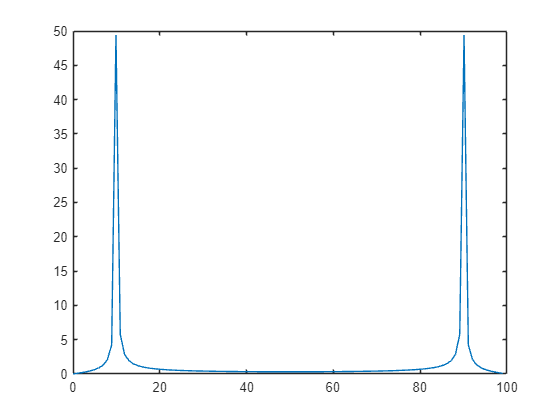

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Sigal Generation Example %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Generating signals
t = 0:0.01:1;
signal = sin(2*pi*10*t);

% Sampling and quantization
fs = 100;   % sampling freuquency
ts = 1/fs;
n = 0:ts:1;
sampled_signal = sin(2*pi*10*n);

%Fourier transform
fft_signal = fft(signal);
f = (0:length(fft_signal)-1)*fs/length(fft_signal);
plot(f, abs(fft_signal));

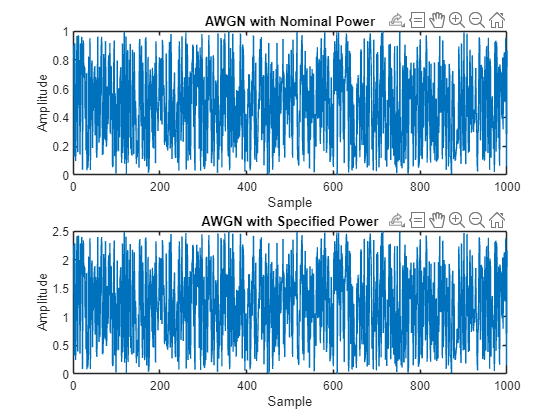


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Generating AWGN with Specified Power %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Generating AWGN with nominal power
N = 1000;   % number of samples
noise = rand(1, N);

% Generating AWGN with specified power
specified_power = 0.5;
noise_power = var(noise);
scaling_factor = sqrt(specified_power/noise_power);
scaled_noise = noise*scaling_factor;    % scale the noise

% Visualizing the noise
figure;
subplot(2,1,1);
plot(noise);
title('AWGN with Nominal Power');
xlabel('Sample');
ylabel('Amplitude');

subplot(2,1,2);

plot(scaled_noise);
title('AWGN with Specified Power');
xlabel('Sample');
ylabel('Amplitude');

## Part B

N = 1000;
transmission_signal = randi([0,1], 1, N);

transmission_signal =      0     0     1     0     1     0     1     1     0     1     1     1     1     1     1     0     1     0     0     1     0     0     1     1     1     1     0     0     0     0     1     1     0     0     1     1     0     0     0     0     0     0     0     1     0     0     0     0     1     0
